Sphere parameters

x0 =3

x0 = 3

y0 = 2

z0 = 4

r = 0.1000

numInliers = 1000

W =      9     6    12     4     8    16


rndNum = 25

y0 = 2
z0 = 4
r =0.1
numInliers =1000%350 pöttyös
W = [x0^2 x0*y0 x0*z0 y0^2 y0*z0 z0^2]

Camera parameters

f = 2000;%1050;
u0 = 2000;
v0 = 2000;
fu = f;
fv = f;
intrinsic = cameraIntrinsics([fu fv], [u0 v0], [2*u0, 2*v0]);

Inlier parameters

rndNum = 25%350 pöttyös
precision_pix = 0;

Generate rndNum inlier point

s = SphereConverter([x0, y0, z0, r]);
pE = sphereO2parametricEllipseO(s);
inliers_m = generateEllipsePoints(pE, numInliers);
%outliers_m = [-0.065 -0.011] + [0:0.001:0.01; zeros(11, 1)']';
%inliers_m = [inliers_m; outliers_m]; 
if precision_pix == 0
    inliers_pix = round(ImageData.meter2pixel(inliers_m, intrinsic));
else
    inliers_pix = round(ImageData.meter2pixel(inliers_m, intrinsic) / precision_pix) * precision_pix;
end
inliers_pix_min = unique(inliers_pix,'rows');
idxs = randsample(length(inliers_m), rndNum);
rndN_pix = inliers_pix(idxs(:),:);
rndN_m = ImageData.pixel2meter(rndN_pix, intrinsic);

rndN_m = inliers_m ;
%rndN_m= inliers_m(idxs(:),:);

Estimate implicit ellipse parameter ground truth

EP_GT = sphereO2implicitEllipseO(s);

Estimators 

pts = PointSet2D(rndN_m);
%{
tic;
sphereSun = fitSphereSun16(pts, r)

lsqr converged at iteration 2 to a solution with relative residual 4e-12.


sphereSun =   SphereConverter with properties:

    parameters: [3.0000 2.0000 4.0000 0.1000]
            s0: [3.0000 2.0000 4.0000]
             r: 0.1000


toc;

Elapsed time is 0.013918 seconds.


EP_Sun = sphereO2implicitEllipseO(sphereSun);

toc;

Elapsed time is 0.017876 seconds.


sphereProp = fitSphere(pts, r)

sphereProp =   SphereConverter with properties:

    parameters: [3.0000 2.0000 4.0000 0.1000]
            s0: [3.0000 2.0000 4.0000]
             r: 0.1000


toc;

Elapsed time is 0.027607 seconds.



tic;
pE_Shi19 = fitEllipseShi19B(pts, r);

A3


toc;

Elapsed time is 0.343754 seconds.


tic;
pE_Dir = fitEllipse(pts);
toc;

Elapsed time is 0.006686 seconds.


ellipseShi19 = EllipseConverter(pE_Shi19);
ellipseDir = EllipseConverter(pE_Dir);

EP_Shi19 = ellipseShi19.implicitEllipse;
EP_Dir = ellipseDir.implicitEllipse;

s_Shi19 = parametricEllipseO2SphereO(pE_Shi19, r)

s_Shi19 =   SphereConverter with properties:

    parameters: [3.0000 2.0000 4.0000 0.1000]
            s0: [3.0000 2.0000 4.0000]
             r: 0.1000


s_Dir = parametricEllipseO2SphereO(pE_Dir, r)

s_Dir =   SphereConverter with properties:

    parameters: [3.0000 2.0000 4.0000 0.1000]
            s0: [3.0000 2.0000 4.0000]
             r: 0.1000


%}
sphereProp = fitSphereA(pts, r)

Construct symbolic ellipse equation

syms u v;
vars = [u^2; u*v; v^2; u; v; 1];
funcgt(u, v) = EP_GT.coefficients * vars;
funcShi19(u, v) = EP_Shi19.coefficients * vars;
funcSun(u, v) = EP_Sun.coefficients * vars;
funcDir(u, v) = EP_Dir.coefficients * vars;

Plot the ellipse and the inliers

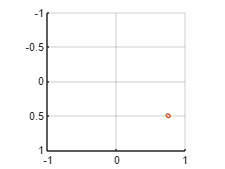

figure;
hold on;
grid on;
axis equal;
set(gca, 'YDir','reverse')
xlim([-u0/f u0/f]);
ylim([-v0/f v0/f]);

% Ellipses
fimplicit(funcgt == 0, [-u0/f u0/f]);
fimplicit(funcShi19 == 0, [-u0/f u0/f]);

fimplicit(funcSun == 0, [-u0/f u0/f]);
fimplicit(funcDir == 0, [-u0/f u0/f]);

% Inliers
scatter(inliers_m(:,1), inliers_m(:,2));
scatter(rndN_m(:, 1), rndN_m(:, 2), 'filled');

% Add legend
lgd = legend( 'ellipseGT', 'ellipseShi19','ellipseSun', 'ellipseDir', 'inliers', 'rndN');

hold off

Plot image with pixels

img = ones(2*v0, 2*u0, 3);
for i = 1 : length(inliers_pix)
    img( inliers_pix(i, 2), inliers_pix(i, 1) , 1:3) = [0 0 1];
end
for i = 1 : length(rndN_pix)
    img( rndN_pix(i, 2), rndN_pix(i, 1) , 1:3) = [1 0 0];
end

figure
hold on;
axis equal;
set(gca, 'YDir','reverse')
xlim([0 2*u0]);
ylim([0 2*v0]);
image(img);
%fimplicit(funcgt == 0, [0 2*u0], 'g','LineWidth',5);
